# Design the PID controller

## Prepare the plant

s = tf('s');
P = tf(16.454, conv([1, 0], conv([0.709, 1], [0.01, 1] )))

P =
 
             16.45
  ---------------------------
  0.00709 s^3 + 0.719 s^2 + s
 
Continuous-time transfer function.



## The Plant is unstable for open loop running

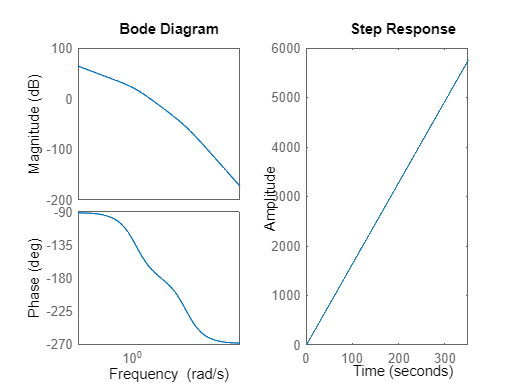

figure
subplot(1,2,1)
bode(P)
subplot(1,2,2)
step(P)

## crossover frequency wf=20 rad/s, phase margin PM=60° 

wf = 20;
PM = 60;

## Design the LADRC

Require phase compensate 67.276
Controller form: PID
PID = Kp(1 + 1/Ti/s + Td*s
Kp : 6.8068
Ti : 0.49765
Td : 0.12441
Design result: 
PM = 60.0001°
wf = 20.0002 rad/s
System BW = 4.9421 Hz


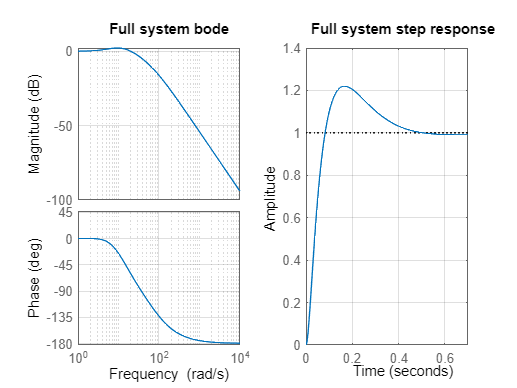

[Kp, Ti, Td, wc] = DesignPID(P, wf, PM);

PID = Kp * (1 + 1/Ti/s + Td * s);
C1 = 1/(Ti/2*s + 1);